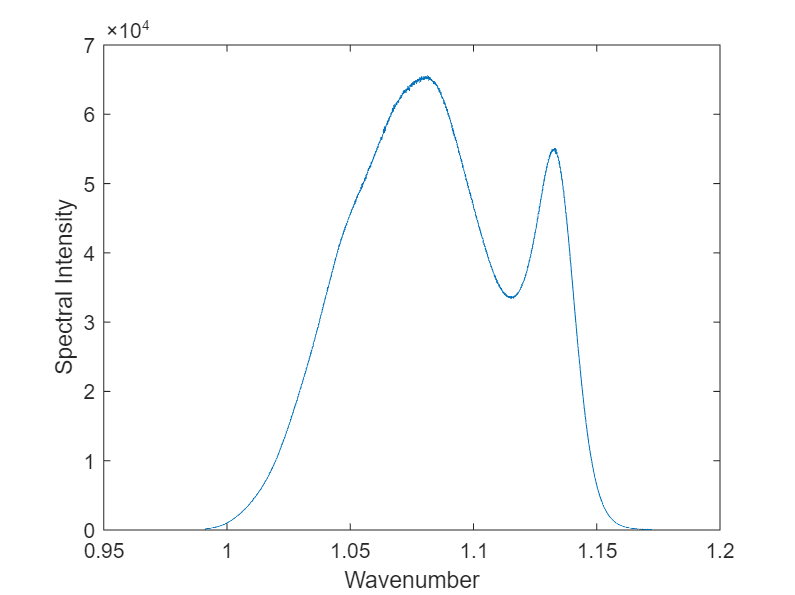

clear; clc;
format short g
%Original spectral interference signal
handle  = OCTFileOpen('Default_0193_Mode2D.oct');
NrRawData = OCTFileGetNrRawData(handle);
[RawData, Spectrum] = OCTFileGetRawData(handle, 0);
load('Wavelength.mat','Wavelength');
% figure(1);plot(1:2048,Wavelength);
% figure(2);plot(Wavelength,Spectrum);
% figure(3);plot(Wavelength,RawData(:,1));
%波数空间采样及线性矫正
%将波长和光谱强度逆序排列
% spectrum = RawData(:,1);
intensity = zeros(1,length(Spectrum));
wavelength = zeros(1,length(Wavelength));
for i = 1:length(Wavelength)
    wavelength(length(wavelength)+1-i) = Wavelength(i);
    intensity(length(intensity)+1-i) = Spectrum(i);
end
%波长映射到波数
sigma = 1./wavelength;
%波数均匀采样
sigma_inter = linspace(sigma(1),sigma(end),length(sigma)); 
%光谱强度三次样条插值
intensity_inter = spline(sigma,intensity,sigma_inter);
figure(4);plot(sigma_inter,intensity_inter);
xlabel('Wavenumber');ylabel('Spectral Intensity');

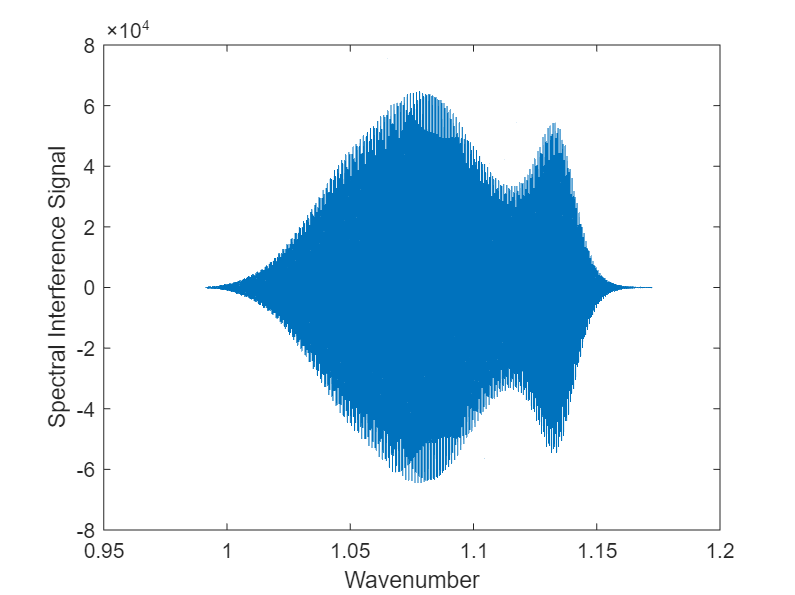

%光谱干涉信号S(\sigma) = A(\sigma)*cos(4\pi*(z-z0)*\sigma-4\pi*T*n(\sigma)*\sigma)
spec_signal = intensity_inter;

%设置参数：
z1 = 1000;
z0 = 0;
T = 20000;
%加入色散
%色散公式
lambda = 1./sigma_inter;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./(lambda.^2-103.560653)+...
        (0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));

interference_signal = spec_signal.*cos(4*pi*(z1-z0).*sigma_inter-4*pi*T*sigma_inter.*index);%+2*spec_signal;
interference_signal1 = interference_signal;
figure(5);plot(sigma_inter,interference_signal);
xlabel('Wavenumber');ylabel('Spectral Interference Signal');

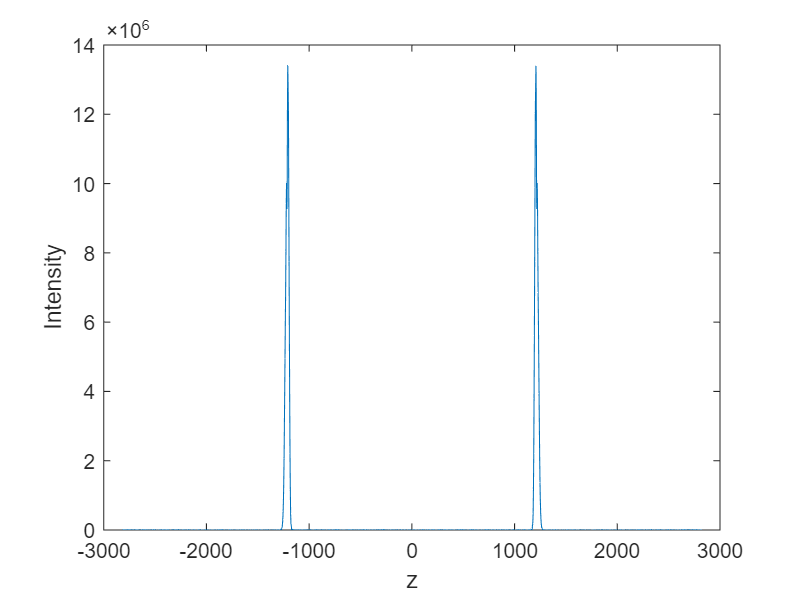

%对光谱进行傅里叶变换
Nfft = 2^20;
fft_signal = fft(interference_signal,Nfft);
interference_signal = fftshift(fft_signal);
deltaSigma = (sigma_inter(end)-sigma_inter(1))/(length(sigma_inter)-1);
deltaZ = 1/(2*Nfft*deltaSigma);
z = (1:Nfft)*deltaZ;
intensity_fft = abs(interference_signal);
angle_fft = angle(interference_signal);
%坐标变换
z = z-z(end)/2;
figure(6);plot(z,intensity_fft);
xlabel('z');ylabel('Intensity');

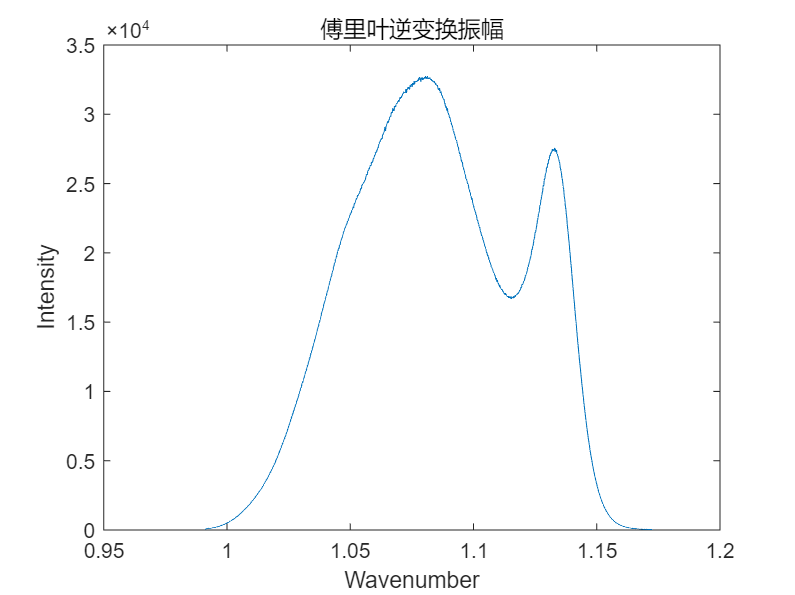

% figure(7);plot(z,unwrap(angle_fft));

%傅里叶逆变换
ifft_signal = interference_signal(length(interference_signal)/2+1:end);
Nfft = 2^20;
ifft_signal = ifft(ifft_signal,Nfft);
interference_signal = ifftshift(ifft_signal);
deltaz = (z(end)-z(1))/(length(z)-1);
deltasigma = 1/(2*Nfft*deltaz);
sigma = (1:Nfft)*deltasigma;
intensity_ifft = abs(interference_signal);
angle_ifft = angle(interference_signal);
%坐标变换
sigma = sigma-sigma(end)/2+sigma_inter(1);
[~, indix_min] = min(abs(sigma-sigma_inter(1)));
[~, indix_max] = min(abs(sigma-sigma_inter(end)));
figure(6);plot(sigma(indix_min:indix_max),intensity_ifft(indix_min:indix_max));
xlabel('Wavenumber');ylabel('Intensity');title("傅里叶逆变换振幅")

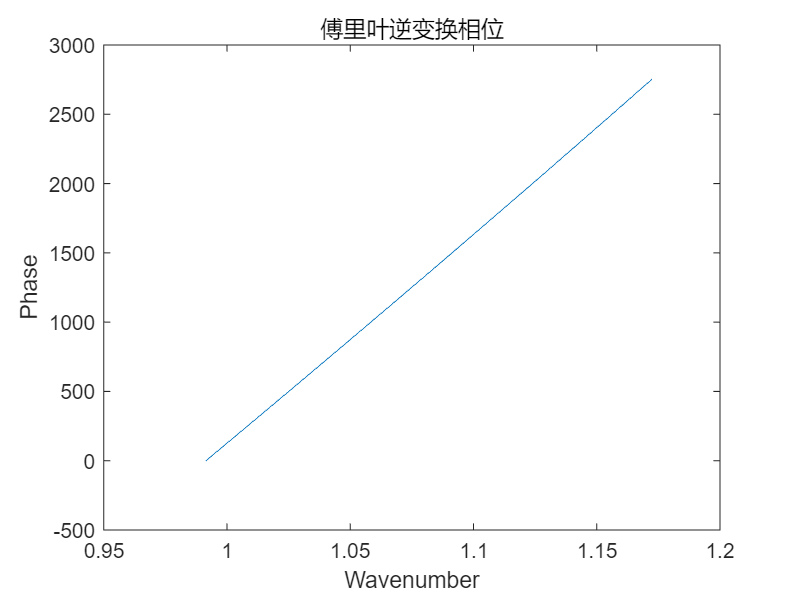

figure(7);plot(sigma(indix_min:indix_max),unwrap(angle_ifft(indix_min:indix_max)));
xlabel('Wavenumber');ylabel('Phase');title("傅里叶逆变换相位")

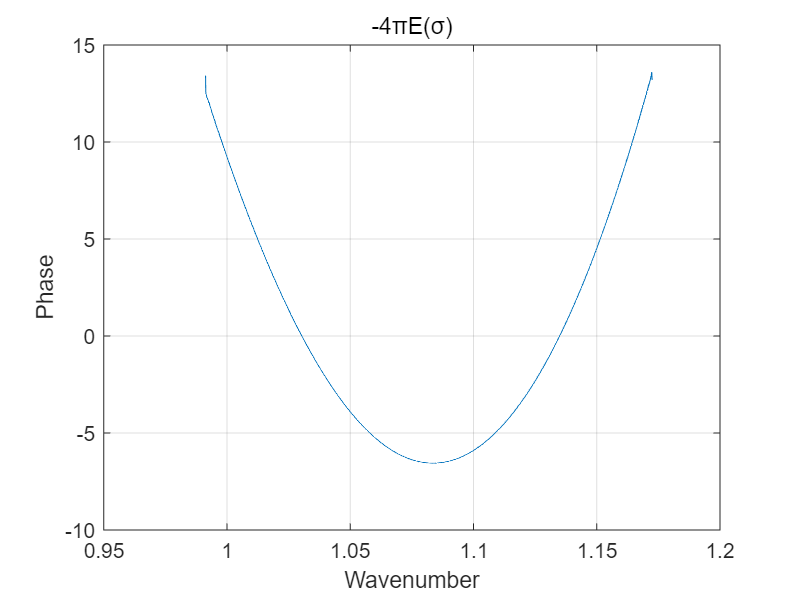


%数据拟合,得到4*pi*E = ang_fit-angle_fit
sigma = sigma(indix_min:indix_max);angle_fit = unwrap(angle_ifft(indix_min:indix_max));
poly = polyfit(sigma,angle_fit,1);
ang_fit = polyval(poly,sigma);
plot(sigma,angle_fit-ang_fit);
xlabel('Wavenumber');ylabel('Phase');title("-4\piE(\sigma)");

%求峰值振幅最大值，半高宽
z = z(length(z)/2+1:end);
intensity_fft = intensity_fft(length(intensity_fft)/2+1:end);
% plot(z,intensity_fft);
grid

threshold = max(intensity_fft)/1.2;
findpeaks(intensity_fft,z,'MinPeakHeight',threshold,'Annotate','extents')
[pks,locs,w,p] = findpeaks(intensity_fft,z,'MinPeakHeight',threshold,'Annotate','extents')

pks =    1.3405e+07


locs =        1208.4


w =        35.457


p =    1.3405e+07


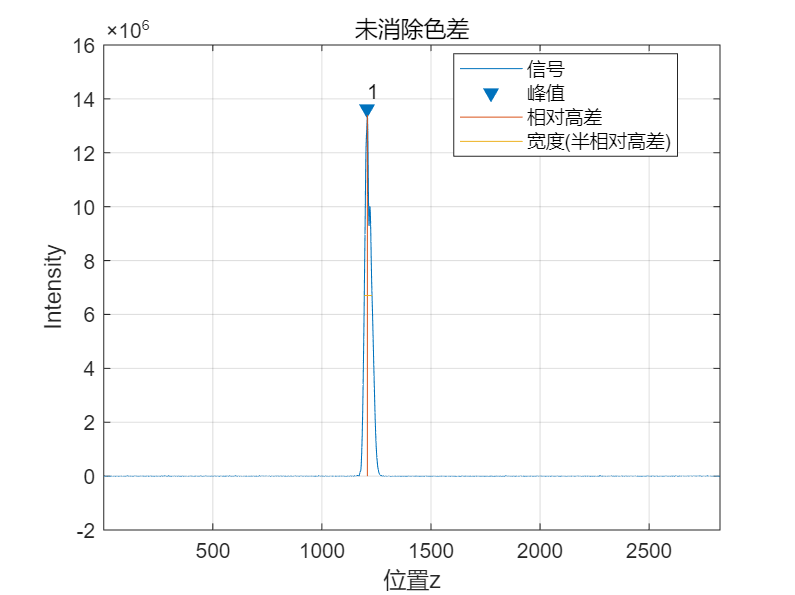

text(locs,pks+pks/15,num2str((1:numel(pks))'));
xlabel('位置z');ylabel('Intensity');title("未消除色差");

%----------------------------------------------------------------------------------------
%求系数C
C = 1/(poly(1)/(4*pi))

C =    0.00082614


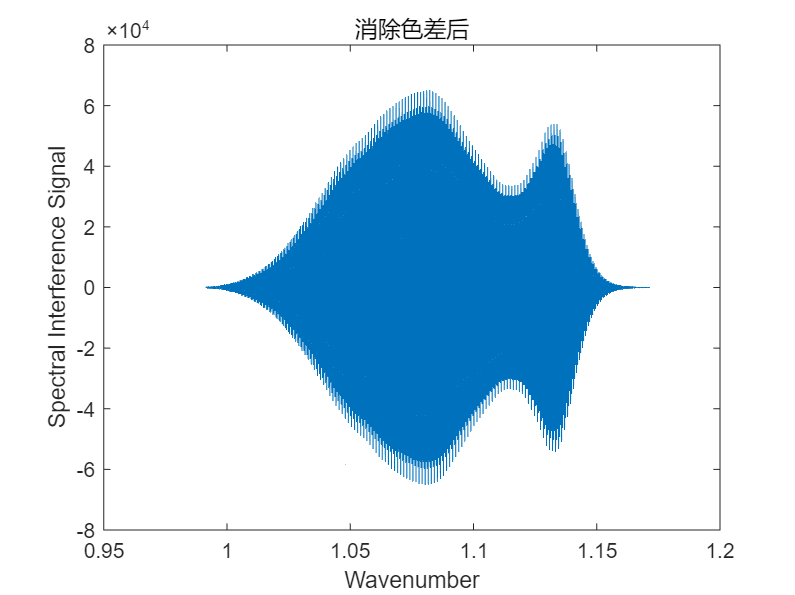

%将sigma用sigma+C*E(sigma)替代
sigma_inter1 = sigma_inter+C*(angle_fit-ang_fit)/(-4*pi);
%插值求得处理后的干涉信号,需要修正，首尾坐标选取sigma_inter、sigma_inter1中合适的值
sigma_find = (sigma_inter1>=sigma_inter(1) & sigma_inter1 <=sigma_inter(end));
sigma_inter1 = sigma_inter1(sigma_find);
signal_C = interp1(sigma_inter,interference_signal1,sigma_inter1,'spline');
plot(sigma_inter1,signal_C)
xlabel('Wavenumber');ylabel('Spectral Interference Signal');title("消除色差后");

%对光谱进行傅里叶变换
Nfft = 2^20;
fft_signal = fft(signal_C,Nfft);
interference_signal = fftshift(fft_signal);
deltaSigma = (sigma_inter1(end)-sigma_inter1(1))/(length(sigma_inter1)-1);
deltaZ = 1/(2*Nfft*deltaSigma);
z = (1:Nfft)*deltaZ;
intensity_fft = abs(interference_signal);
angle_fft = angle(interference_signal);
%坐标变换
z = z-z(end)/2;
z = z(length(z)/2+1:end);
intensity_fft = intensity_fft(length(intensity_fft)/2+1:end);
% plot(z,intensity_fft);
threshold = max(intensity_fft)/1.2;
findpeaks(intensity_fft,z,'MinPeakHeight',threshold,'Annotate','extents')
[pks,locs,w,p] = findpeaks(intensity_fft,z,'MinPeakHeight',threshold,'Annotate','extents')

pks =    3.2039e+07


locs =        1210.9


w =        5.3357


p =    3.2039e+07


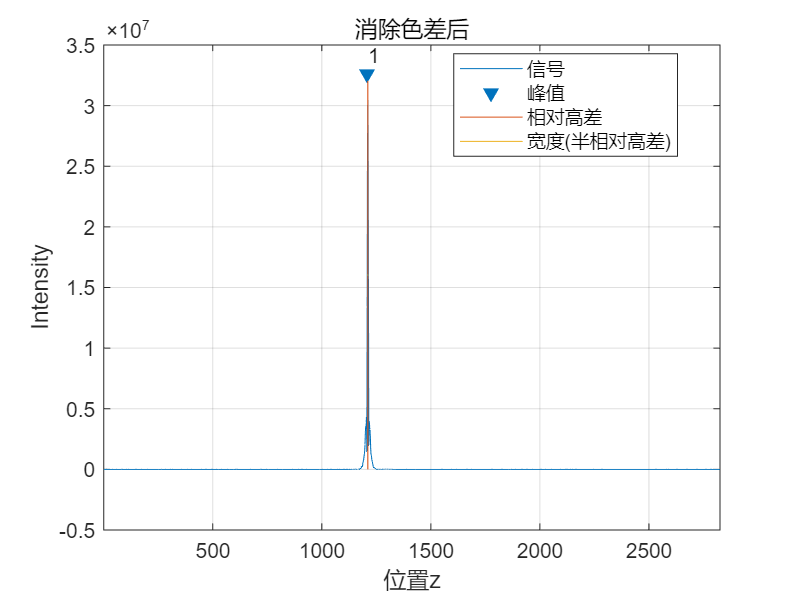

text(locs,pks+pks/15,num2str((1:numel(pks))'));
xlabel('位置z');ylabel('Intensity');title("消除色差后");